Torque area - Falde tryk

clear
clf

% A = 1593 * 2; %mm^2
r_outer = [0.054 0.034 0.030]

r_outer =     0.0540    0.0340    0.0300


A_current = 512 * 2 %mm^2 % 512

A_current = 1024

T = [10e3 1e3 0.1e3];
S = T./r_outer / A_current

S =   180.8449   28.7224    3.2552



n_y = 2; %Sikkerheds factor
S_y = 375; %375 - 460 % edu pack C45 - AISI 1040
S_max =  S_y / n_y

S_max = 187.5000

syms A_sym

A_min_eq = S_max == T(1)/r_outer(1) / (A_sym*2);
A_min_sol = double(solve(A_min_eq, A_sym))

A_min_sol = 493.8272

A_min_eq = S_max == T(2)/r_outer(2) / (A_sym*2);
A_min_sol = double(solve(A_min_eq, A_sym))

A_min_sol = 78.4314

A_min_eq = S_max == T(3)/r_outer(3) / (A_sym*2);
A_min_sol = double(solve(A_min_eq, A_sym))

A_min_sol = 8.8889

Aksel for dimentionering

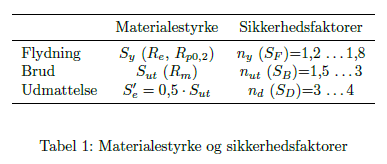

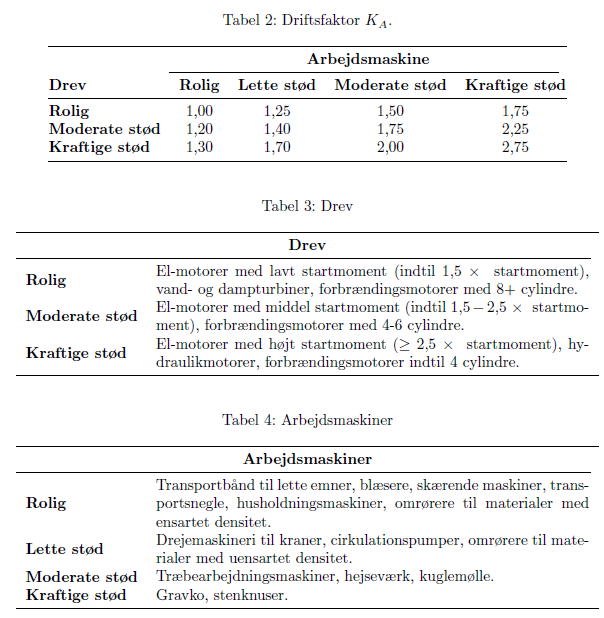

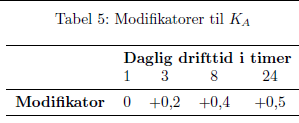

 at yield

For solid shaft

% K_a = 1.0; % tabel 2,3,4 and 5 in "Fordimensionering af aksler"
T_max = [10e3 10e3 1e3 0.1e3];% * K_a; %Nm

% d = 95e-3; %mm
n_y = 2; %drev Kraftige stød % arbejds maskinen Lette stød
S_y = 1100; %375 - 460 % edu pack C45 - AISI 1040

% tau_max_Pa = T_max / (pi/16 * d^3) 
% ta_max_MPa = tau_max_Pa/1e6
tau_til = 1/sqrt(3) * S_y / n_y

tau_til = 317.5426


d_m = (T_max / (pi/16  * tau_til * 1e6)).^(1/3)

d_m =     0.0543    0.0543    0.0252    0.0117


d_mm = d_m * 1000

d_mm =    54.3320   54.3320   25.2187   11.7055


For hollow shaft

d = [88e-3 42e-3 30e-3 20e-3] ; % inner diameter
D_sol = zeros(1, length(T_max)); % stand ind for outer diameter
for i = 1:length(T_max)
    syms D
    W_p = pi * (D^4 - d(i)^4)/(16*D); %MMTH page 46 
    D_eq = tau_til*1e6 == T_max(i) / W_p; % setting up equation
    
    D_sol = solve(D_eq, D); %solving for outer diameter
    D_sols(i) = double(D_sol(4));
end

D_sols

D_sols =     0.0930    0.0597    0.0341    0.0210


D_sols_mm = D_sols *1e3

D_sols_mm =    93.0263   59.6769   34.1336   20.9774


Spline

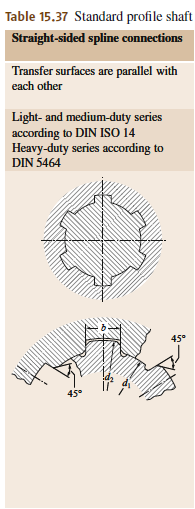Springers

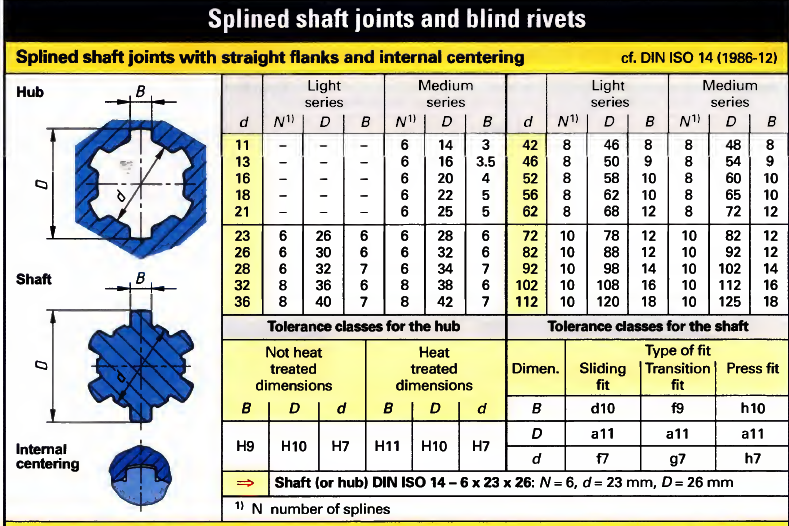MMTH

T_max = [10e3 1e3];
d = [82e-3 42e-3]; % d>77,8 see above %shaft diameter
N = [10 8]; %number of theeth
% D = 92e-3; %medium series outer diameter
D = [88e-3 46e-3]; %light series outer diameter
B = [12 8]; %width of tooth

L = [50e-3 25e-3];%length of spline interacion
r = (D./2 - (D-d)./2)

r =     0.0410    0.0210


F = T_max ./ r

F = 1.0e+05 *

    2.4390    0.4762


A = (D-d)./2 .* L %areal i kontakt pr spline

A = 1.0e-03 *

    0.1500    0.0500


S_Pa = F ./ (A .* N)

S_Pa = 1.0e+08 *

    1.6260    1.1905


S_MPA =S_Pa /1e6

S_MPA =   162.6016  119.0476


Spline holds on Light series

DIN 5480-16 2006

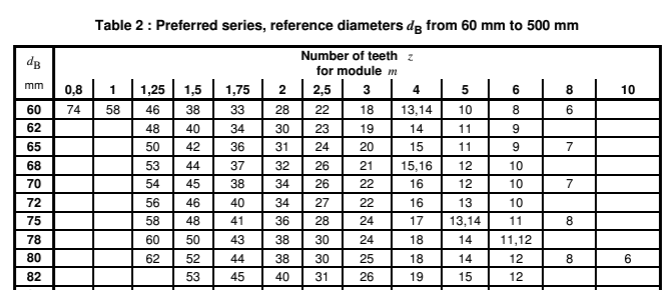

% d_B

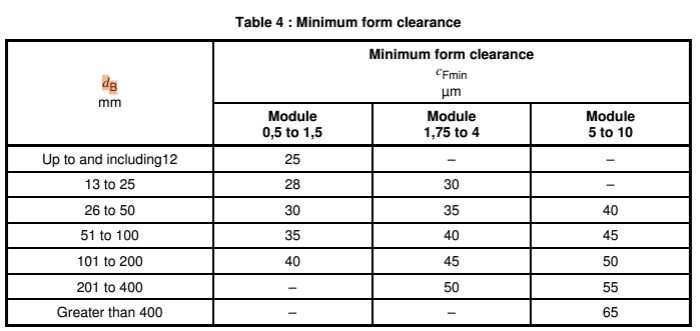

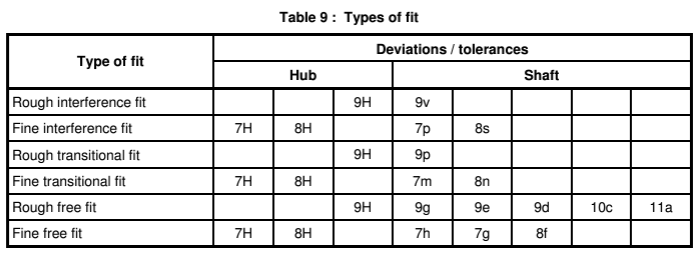

shaft 9e

hub 9H

se side 103 i den blå

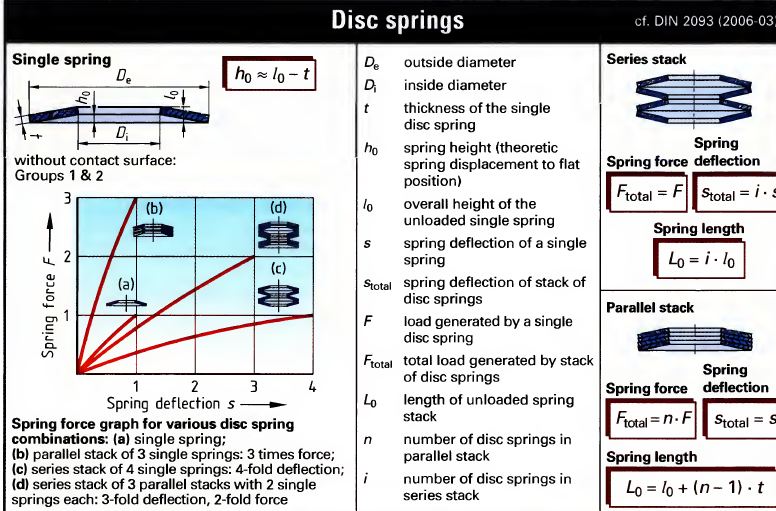

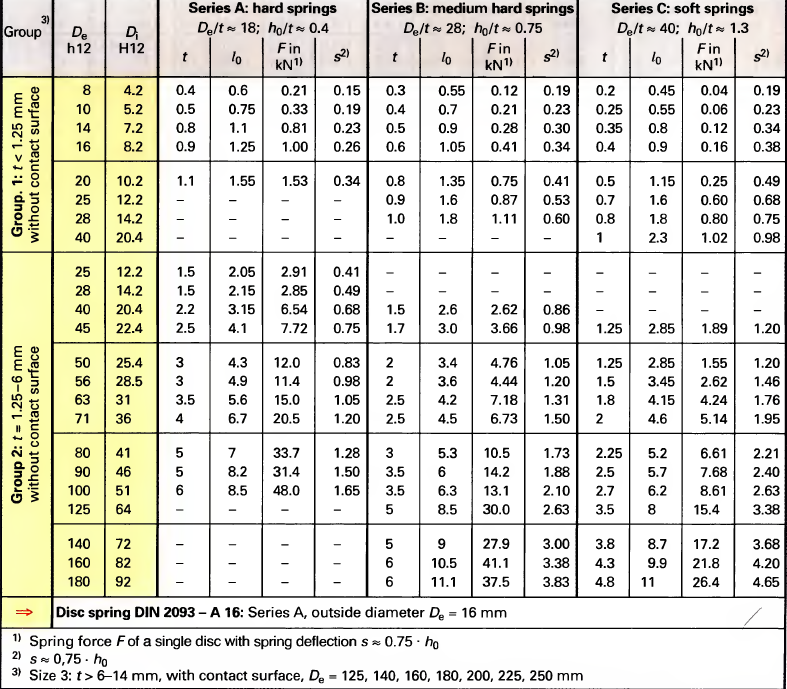

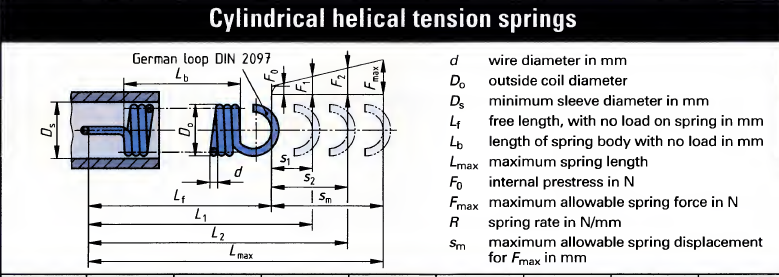

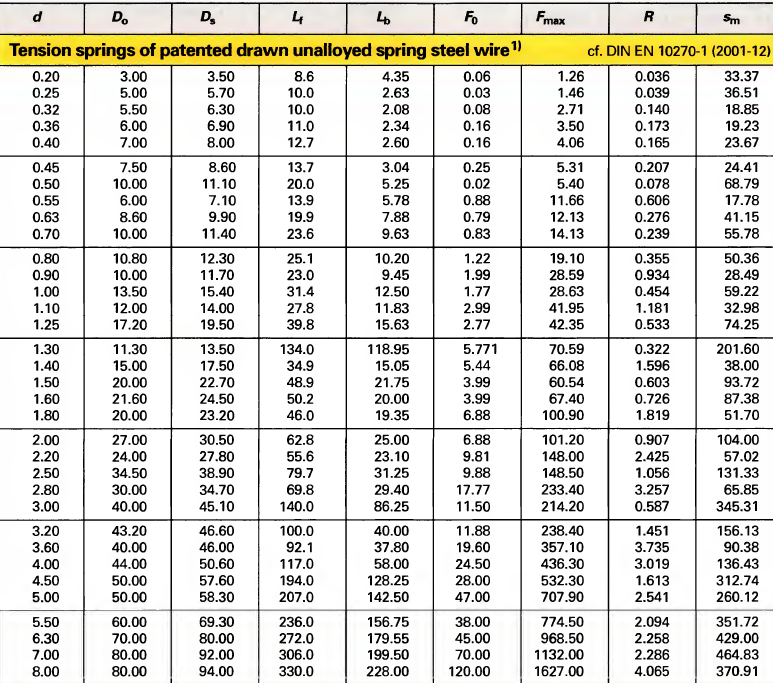

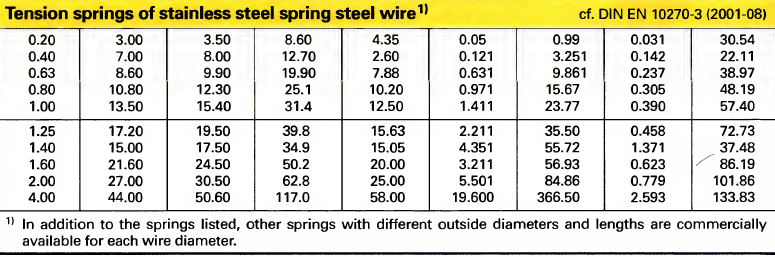

## Spring energi calculations

**Assumptions:**

- Frictionless rotor

- Frictionless push on rotor

- The equivalence principle

- Linear spring konstant

100 Nm tranducer

**Motor**

clear
clf
theta_release = 11; %rotation for release
r = 0.070/2 - 0.012 % fixed radius % radius where the force is apllied

r = 0.0230

%this is also the approximate middle point of the friction

I = 0.0012; %HMA4 80 1-2
% I = 0.0057;HMA4 90S-6
% I = 0.1617; %HMA4 160L-6
% I = 0.335; % HMC4 225M-2 % possible for 120hz 

%compression of spring if not fully
% T_to_store = F_realese * 2 * r % two springs % how much torque i needed to store energi in the spring
T = 1.2 % minimum torque for 120 Hz 2 pole FS 71, 0.7 for non overload

T = 1.2000

% T = 96 % HMC4 225M-2 at 120 Hz 
F_to_store = T / r % how much torque i needed to store energi in the spring

F_to_store = 52.1739

**Radial spring data**

% C07200630620M % 	fri længde=	15,75 max vandring = 6,96 De=18,29 Di =15,09
% max kraft 62,28
s_spring_max = 2e-3 % Max compression if depends on allowed clearance (measure) 

s_spring_max = 0.0020

k_spring = 9.11e3% spring constant

k_spring = 9110


% T / r = k_spring * s_spring_max % equation for spring coefficient
s_spring_push = T / (r * k_spring * 2) % Spring compresion if not fully compressed

s_spring_push = 0.0029


if s_spring_max > s_spring_push
    s_spring_max = s_spring_push
else
    s_spring_max
end

s_spring_max = 0.0020

F_spring = k_spring * s_spring_max * 2

F_spring = 36.4400

**Axial spring**

f_k = 0.15; %kinetic friction coeffecient for steel vs steel \cite MMTH page 38
%static friction is 0.25
k_axial = 0.57e3; % N/mm --> N/m % max kraft 41,87, max vandring 66,80, total lenth 123,95 L0 = 57,15
% E08500632250S % varenummer trækfjeder SODEMANN
l_0 = 57.15;
x_axial = (111 - l_0)*1e-3%55e-3; % udspændt fjeder til træk af claw

x_axial = 0.0539

F_axial = k_axial * x_axial

F_axial = 30.6945

F_fric = F_axial * f_k

F_fric = 4.6042

**Energi**

thetas = 0:0.05:12; % angle traveled
theta_spring_release = atand(s_spring_max/r) % 

theta_spring_release = 4.9697

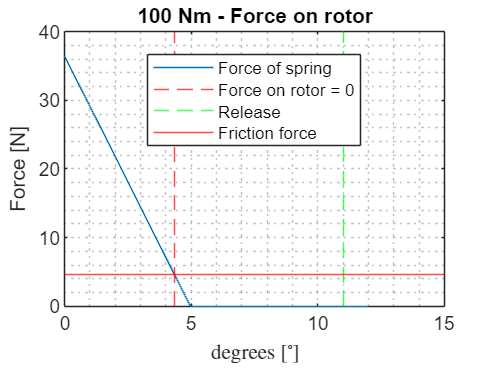

syms omega s_spring_sym

for i = 1:length(thetas)
    
    %r^2 + r^2 - 2*r*r * cosd(thetas(i))
    if  thetas(i) < theta_spring_release%x < s_spring_max
        s_spring = sqrt(2 * r^2 - 2*r^2 * cosd(thetas(i))); %cos sin relations 
        s_spring = tand(thetas(i)) * r;
        % spring push distance
    else
        s_spring = s_spring_max;
    end
    
    % finding the force on the rotor
    F_spring(i) = k_spring * (s_spring_max - s_spring) * 2; %two spring sides
    F_spring_eq = k_spring * (s_spring_max - s_spring_sym) * 2; %two spring sides

    % finding the energi
    W_spring_eq = int(F_spring_eq, s_spring_sym, 0, s_spring);
    W_spring_eq = int(F_spring_eq, s_spring_sym, 0, s_spring);
    W_spring = double(W_spring_eq); 

    if W_spring > 0
        % W_spring
    else
        W_spring = 0;
    end

    x = 2*pi*r * thetas(i)/360; % travel on the circle

    W_fric = F_fric * x;

    W_total(i) = W_spring - W_fric; 

    % calculating the angular speed
    omega_eq = 1/2 * I * omega^2 == W_spring - W_fric; 
    omega_sol1 = solve(omega_eq, omega);
    omega_sol2(i) = double(omega_sol1(2));
end

[max_value, max_index] = max(W_total);
theta_spring_max = thetas(max_index); % holder for max spring

plot(thetas, F_spring, DisplayName="Force of spring")
hold on
xline(theta_spring_max, 'r--', DisplayName='Force on rotor = 0')
xline(theta_release, 'g--', DisplayName='Release')
yline(F_fric, 'r', DisplayName="Friction force")
ylabel("Force [N]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("100 Nm - Force on rotor")
hold off

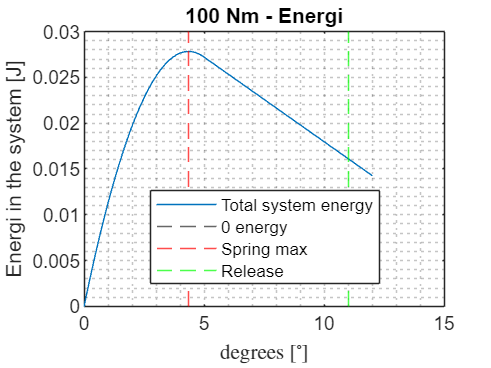


plot(thetas, W_total, DisplayName="Total system energy")
hold on
yline(0, '--', DisplayName="0 energy")
xline(theta_spring_max, 'r--', DisplayName='Spring max')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Energi in the system [J]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("100 Nm - Energi")
hold off

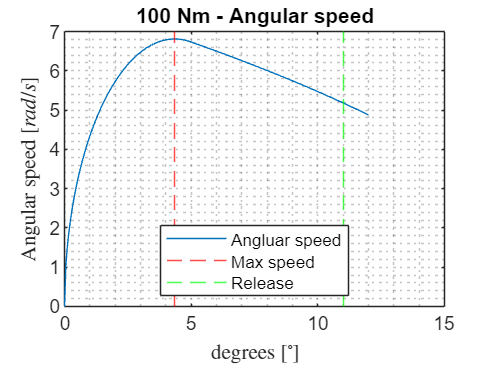


plot(thetas, omega_sol2, DisplayName="Angluar speed")
hold on
xline(theta_spring_max, 'r--', DisplayName='Max speed')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Angular speed $[rad/s]$", Interpreter="latex")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("100 Nm - Angular speed")
hold off

1 kNm tranducer

**Motor data**

clear
clf
theta_release = 11; %rotation for release
r = 0.025; %0.092/2 - 0.012 % fixed radius % radius where the force is apllied
%this is also the approximate middle point of the friction

I =  0.0095; % HMA4 112M-2
% I = 0.1617; %HMA4 160L-6
% I = 0.335; % HMC4 225M-2
% I = 1; % inertia of the test motor 
% I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 5.7105; % HMC4 315L2-6

%compression of spring if not fully
% T_to_store = F_realese * 2 * r % two springs % how much torque i needed to store energi in the spring
T = 102 % minimum torque for 10 Hz 2 pole FS 112

T = 102

% T = 934 % minimum torque for 120 Hz 6 pole FS 315 (HMC4 315L2-6)
F_to_store = T / r % how much torque i needed to store energi in the spring

F_to_store = 4080


P_fr = 454.43;

**Radial spring data**

n_stack_para = 1; %number of paralel stacked disc springs for more force
% (stacked same way)
n_stack_series = 2; %number of series stacked disc springs for more force
% (stacked opposite way)
F_realese = 553 * n_stack_para; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
s_spring_max = 0.5e-3 * n_stack_series; %(0.53e-3)
k_spring = F_realese / s_spring_max

k_spring = 553000


% T / r = k_spring * s_spring_max
s_spring_push = T / (r * k_spring * 2) % Spring compresion if not fully compressed

s_spring_push = 0.0037


if s_spring_max > s_spring_push
    s_spring_max = s_spring_push
else
    s_spring_max
end

s_spring_max = 1.0000e-03

F_spring = k_spring * s_spring_max * 2 % two radial springs

F_spring = 1106

**Axial spring**

f_k = 0.15; %kinetic friction coeffecient for steel vs steel \cite MMTH
k_axial = 1.77e3; % N/mm --> N/m % max kraft 137,09, max vandring 70,36, total lenth 159,26 L0 = 	88,90
% E07500853500M % varenummer trækfjeder SODEMANN
%49,3
% x_axial = 49.3e-3;%65e-3; % udspændt fjeder til træk af claw
% F_axial = k_axial * x_axial
% F_fric = F_axial * f_k

f_k = 0.15; %kinetic friction coeffecient for steel vs steel \cite MMTH
L0 = 57.15e-3; % free length
L_extended = 111e-3;
L_retracted = 77e-3;
L_full = 124e-3

L_full = 0.1240

k_axial = 0.57e3; % N/mm --> N/m % max kraft 41,87, max vandring 66,80, total lenth 123,95 L0 = 57,15
% E08500632250S % varenummer trækfjeder SODEMANN
x_axial = (L_full - L0) % 55e-3; % udspændt fjeder til træk af claw

x_axial = 0.0668



x_spring_pre = (L_retracted - L0)

x_spring_pre = 0.0198

%down to 77 from 110 (44)
F_axial_pre = k_axial * x_spring_pre

F_axial_pre = 11.3145

F_axial = k_axial * x_axial

F_axial = 38.1045

F_fric = F_axial * f_k

F_fric = 5.7157

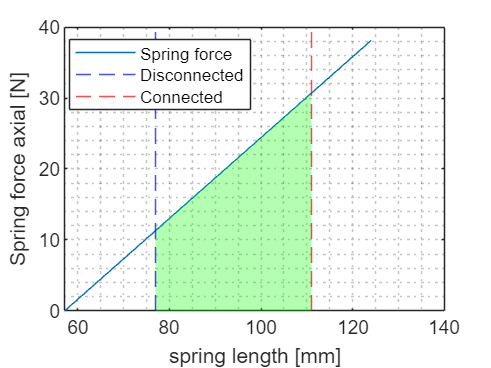


X = linspace(L0,L_full,100);
F_axial_plot = k_axial * (X-L0);
plot(X*1e3, F_axial_plot, DisplayName="Spring force")
hold on

fill_X = [linspace(L_retracted, L_extended, 100), L_extended, L_retracted]; % Extend to close area
fill_Y = [k_axial * (linspace(L_retracted, L_extended, 100) - L0), 0, 0]; % Add zeros for base
fill(fill_X * 1e3, fill_Y, 'g', 'FaceAlpha', 0.3, ...
    EdgeColor='none',HandleVisibility='off') % Fill with green color



xline(L_retracted*1e3, 'b--', DisplayName="Disconnected")
xline(L_extended*1e3, 'r--', DisplayName="Connected")

xlabel("spring length [mm]")
ylabel("Spring force axial [N]")
legend('Location', 'best')
grid('minor')
hold off

**Energi**

thetas = 0:0.05:12; % angle traveled
theta_spring_release = atand(s_spring_max/r) % 

theta_spring_release = 2.2906

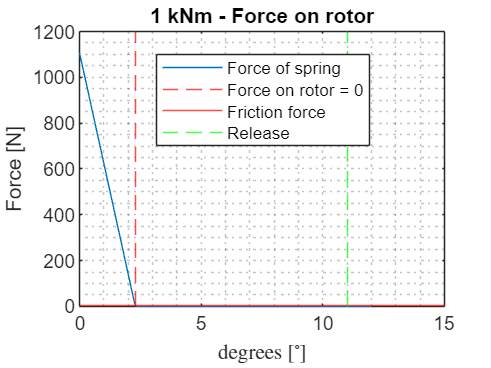

syms omega s_spring_sym

for i = 1:length(thetas)
    
    %r^2 + r^2 - 2*r*r * cosd(thetas(i))
    if  thetas(i) < theta_spring_release%x < s_spring_max
        s_spring = sqrt(2 * r^2 - 2*r^2 * cosd(thetas(i))); %cos sin relations 
        s_spring = tand(thetas(i)) * r;
        % spring push distance
    else
        s_spring = s_spring_max;
    end
    
    % finding the force on the rotor
    F_spring(i) = k_spring * (s_spring_max - s_spring) * 2; %two spring sides
    F_spring_eq = k_spring * (s_spring_max - s_spring_sym) * 2; %two spring sides

    % finding the energi
    W_spring_eq = int(F_spring_eq, s_spring_sym, 0, s_spring);
    W_spring = double(W_spring_eq); 

    if W_spring > 0
        % W_spring
    else
        W_spring = 0;
    end

    x = 2*pi*r * thetas(i)/360; % travel on the circle
    W_fric = F_fric * x;
    W_total(i) = W_spring - W_fric; 

    % calculating the angular speed
    omega_eq = 1/2 * I * omega^2 == W_spring - W_fric; 
    omega_sol1 = solve(omega_eq, omega);
    omega_sol2(i) = double(omega_sol1(2));
end

[max_value, max_index] = max(W_total);
theta_spring_max = thetas(max_index); % holder for max spring

plot(thetas, F_spring, DisplayName="Force of spring")
hold on
xline(theta_spring_max, 'r--', DisplayName='Force on rotor = 0')
yline(F_fric, 'r', DisplayName="Friction force")
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Force [N]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("1 kNm - Force on rotor")
hold off

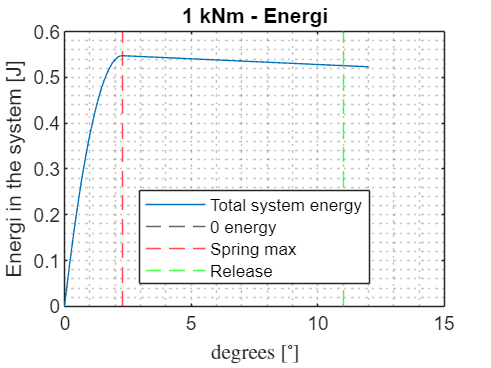


plot(thetas, W_total, DisplayName="Total system energy")
hold on
yline(0, '--', DisplayName="0 energy")
xline(theta_spring_max, 'r--', DisplayName='Spring max')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Energi in the system [J]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("1 kNm - Energi")
hold off

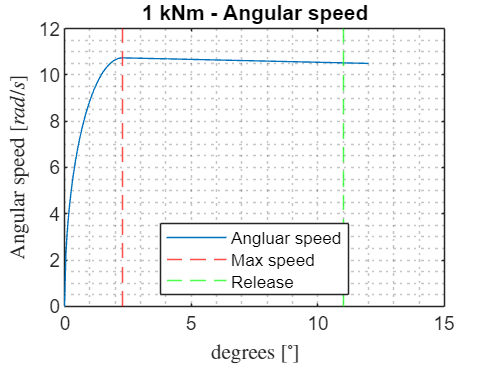


plot(thetas, omega_sol2, DisplayName="Angluar speed")
hold on
xline(theta_spring_max, 'r--', DisplayName='Max speed')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Angular speed $[rad/s]$", Interpreter="latex")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("1 kNm - Angular speed")
hold off

10 kNm tranducer

Radial spring data

**Motor data**

clear
clf
theta_release = 11; %rotation for release
r = 0.132/2 - 0.012 % fixed radius % radius where the force is apllied

r = 0.0540

%this is also the approximate middle point of the friction

% I = 0.2554; % HMC4 180L-6
% I = 0.335; % HMC4 225M-2
% I = 1; % inertia of the test motor 
% I = 3.68; % inertia of the test motor % HMC4 355L-2
% I = 12.79; % inertia of the test motor % HMC4 355L-6
I = 15.9356; % inertia of the test motor % HMC3 355L-6

%compression of spring if not fully
% T_to_store = F_realese * 2 * r % two springs % how much torque i needed to store energi in the spring
% T = 1121 % minimum torque for 10 Hz 4 pole FS 180
T = 8149 % minimum torque for 120 Hz 6 pole FS 400

T = 8149

F_to_store = T / r % how much torque i needed to store energi in the spring

F_to_store = 1.5091e+05

**Radial spring data**

n_stack_para = 1; %number of paralel stacked disc springs for more force
% (stacked same way)
n_stack_series = 2; %number of series stacked disc springs for more force
% (stacked opposite way)
F_realese = 553 * n_stack_para; % N = k * x  % max vandirng 0,53 ;frilængde 1,40, ved belastning 0,88, D_udvendig = 18,00mm
s_spring_max = 0.5e-3 * n_stack_series; %(0.53e-3)
k_spring = F_realese / s_spring_max

k_spring = 553000


% T / r = k_spring * s_spring_max
s_spring_push = T / (r * k_spring * 2) % Spring compresion if not fully compressed

s_spring_push = 0.1364


if s_spring_max > s_spring_push
    s_spring_max = s_spring_push
else
    s_spring_max
end

s_spring_max = 1.0000e-03

F_spring = k_spring * s_spring_max * 2

F_spring = 1106

% A = 283.5 * 2 % test of surface presure on spring buffer
% S = F_spring / A - OK

**Axial spring**

f_k = 0.15; %kinetic friction coeffecient for steel vs steel \cite MMTH
k_axial = 1.77e3; % N/mm --> N/m % max kraft 137,09, max vandring 70,36, total lenth 159,26 L0 = 	88,90
% E07500853500M % varenummer trækfjeder SODEMANN
x_axial = 65e-3; % udspændt fjeder til træk af claw
F_axial = k_axial * x_axial

F_axial = 115.0500

F_fric = F_axial * f_k

F_fric = 17.2575


% 44.24mm pull 
% l = 117,6 (100)

**Energi**

thetas = 0:0.05:12; % angle traveled
theta_spring_release = atand(s_spring_max/r) % 

theta_spring_release = 1.0609

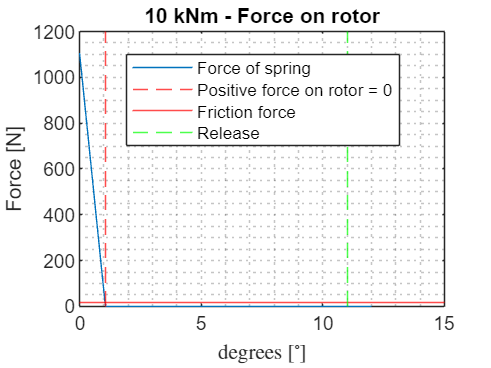

syms omega s_spring_sym

for i = 1:length(thetas)
    
    %r^2 + r^2 - 2*r*r * cosd(thetas(i))
    if  thetas(i) < theta_spring_release%x < s_spring_max
        s_spring = sqrt(2 * r^2 - 2*r^2 * cosd(thetas(i))); %cos sin relations 
        s_spring = tand(thetas(i)) * r;
        % spring push distance
    else
        s_spring = s_spring_max;
    end
    
    % finding the force on the rotor
    F_spring(i) = k_spring * (s_spring_max - s_spring) * 2; %two spring sides
    F_spring_eq = k_spring * (s_spring_max - s_spring_sym) * 2; %two spring sides

    % finding the energi
    W_spring_eq = int(F_spring_eq, s_spring_sym, 0, s_spring);
    W_spring = double(W_spring_eq); 

    if W_spring > 0
        % W_spring
    else
        W_spring = 0;
    end

    x = 2*pi*r * thetas(i)/360; % travel on the circle
    W_fric = F_fric * x;
    W_total(i) = W_spring - W_fric; 

    % calculating the angular speed
    omega_eq = 1/2 * I * omega^2 == W_spring - W_fric; 
    omega_sol1 = solve(omega_eq, omega);
    omega_sol2(i) = double(omega_sol1(2));
end

[max_value, max_index] = max(W_total);
theta_spring_max = thetas(max_index); % holder for max spring

plot(thetas, F_spring, DisplayName="Force of spring")
hold on
xline(theta_spring_max, 'r--', DisplayName='Positive force on rotor = 0')
yline(F_fric, 'r', DisplayName="Friction force")
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Force [N]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("10 kNm - Force on rotor")
hold off

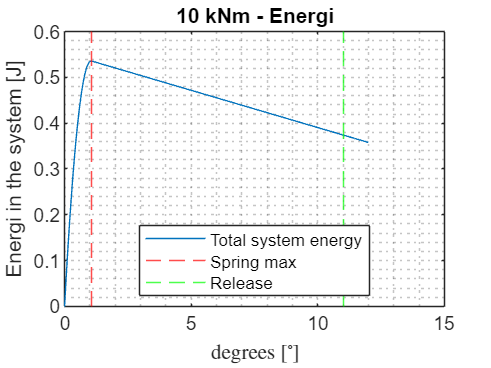


plot(thetas, W_total, DisplayName="Total system energy")
hold on
% yline(0, '--', DisplayName="0 energy")
xline(theta_spring_max, 'r--', DisplayName='Spring max')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Energi in the system [J]")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("10 kNm - Energi")
hold off

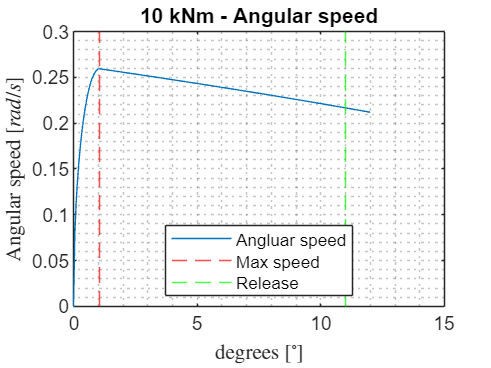


plot(thetas, omega_sol2, DisplayName="Angluar speed")
hold on
xline(theta_spring_max, 'r--', DisplayName='Max speed')
xline(theta_release, 'g--', DisplayName='Release')
ylabel("Angular speed $[rad/s]$", Interpreter="latex")
xlabel("degrees $ [^\circ] $", Interpreter="latex")
grid("minor")
legend(Location="best")
title("10 kNm - Angular speed")
hold off